# Assignment 13 Vehicle tracking based on GPS and odometry data fusion

## Group 6:

## • Andrei Shumeiko

## • Ayush Gupta

## • Olga Klyagina

## • Simona Nitti

# PART 1 Assimilation of GPS data only (absolute positioning)

clc
clear
close all

##  Task 1: Download the file ‘theta.mat'

load('theta.mat')

##  Task 2: Generate a true trajectory of a moving vehicle 

n = 500;   % Size of trajectory 
T = 0.05;  % Interval between measurements

%Initial components of velocity
V = 10;
v = zeros(2,n);

% Initial coordinates
x = zeros(2,n);

% Random acceleration
var_a = 1;
a = sqrt(var_a)*randn(2,n);

for i = 2:n
    x(1,i) = x(1,i-1) + V*T*cos(theta(i-1)) + a(1,i-1)*T^2/2;
    x(2,i) = x(2,i-1) + V*T*sin(theta(i-1)) + a(2,i-1)*T^2/2;
    v(1,i)= V*cos(theta(i-1)); % V_x
    v(2,i)= V*sin(theta(i-1)); % V_y
end

##  Task 3: Generate measurements of 𝑥and 𝑦

var_eta = 3^2;
eta = randn(2,n)*sqrt(var_eta); 
z = x + eta;

##  Task 4: Develop Linear Kalman filter algorithm tolocalize the moving vehicle on the basis

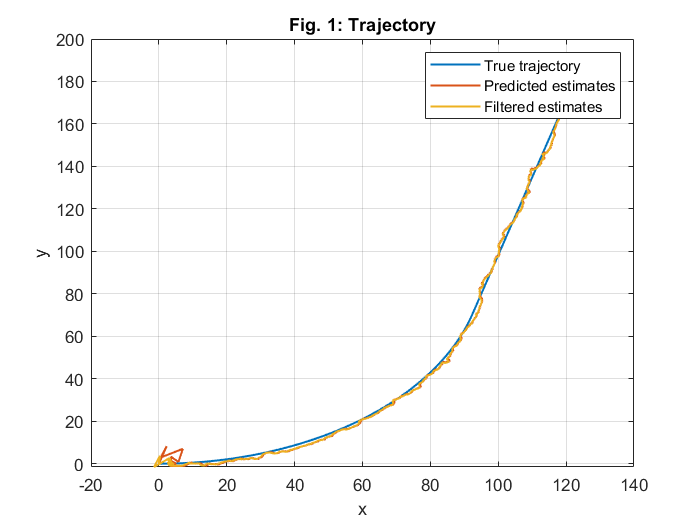

% Transition matrix
phi = eye(4)+ T*diag(ones(3,1),1);
phi(2,3)=0;

% Input matrix
G = [T^2/2 0; T 0; 0 T^2/2;0 T];

% State noise covariance matrix
Q = G*G'*5^2;

% Initial filtered estimate of state vector
X = zeros(4,n);
X(:,2) = [z(1,2) (z(1,2)-z(1,1))/T z(2,2) (z(2,2)-z(2,1))/T]'; 

% Initial filtration error covariance matrix 
P = 1e4*eye(4); 

% Measurement noise covariance matrix R
R = var_eta*eye(2);

% Observation matrix
H = eye(4);
H(2:2:4,:) = [];

% Algorithm
X_pred = zeros(4,n);
for i = 3:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    
    % Filtration 
    K = P_pred*H'*inv(H*P_pred*H'+ R);
    X(:,i) = X_pred(:,i) + K*(z(:,i)-H*X_pred(:,i));
    P = (eye(4)-K*H)*P_pred;
end

figure
plot(x(1,:),x(2,:),'linewidth',1.2)
hold on
plot(X_pred(1,:),X_pred(3,:),'linewidth',1.2)
plot(X(1,:),X(3,:),'linewidth',1.2)
xlabel('x')
ylabel('y')
legend('True trajectory','Predicted estimates','Filtered estimates')
title('Fig. 1: Trajectory')
grid on

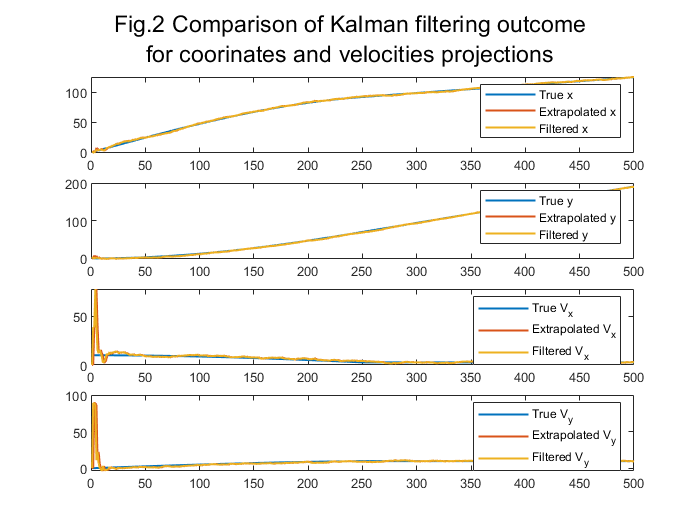


figure
sgtitle({'Fig.2 Comparison of Kalman filtering outcome';...
    'for coorinates and velocities projections'})
subplot(4,1,1)
plot(x(1,:),'linewidth',1.2)
hold on
plot(X_pred(1,:),'linewidth',1.2)
plot(X(1,:),'linewidth',1.2)
legend('True x','Extrapolated x','Filtered x')

subplot(4,1,2)
plot(x(2,:),'linewidth',1.2)
hold on
plot(X_pred(3,:),'linewidth',1.2)
plot(X(3,:),'linewidth',1.2)
legend('True y','Extrapolated y','Filtered y')

subplot(4,1,3)
plot(v(1,:),'linewidth',1.2)
hold on
plot(X_pred(2,:),'linewidth',1.2)
plot(X(2,:),'linewidth',1.2)
legend('True V_x','Extrapolated V_x','Filtered V_x')

subplot(4,1,4)
plot(v(2,:),'linewidth',1.2)
hold on
plot(X_pred(4,:),'linewidth',1.2)
plot(X(4,:),'linewidth',1.2)
legend('True V_y','Extrapolated V_y','Filtered V_y')

##  Task 5: Run Linear Kalman filter

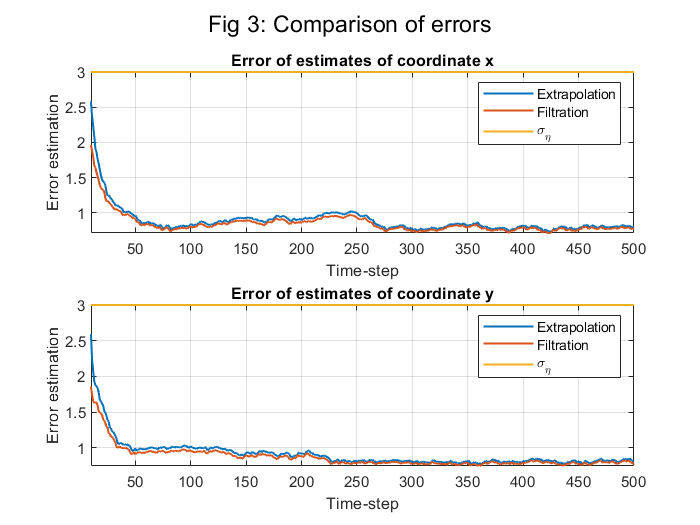

M = 500;

Final_Error_estr_1 = zeros(2,n);
error_estr = zeros(2,n);
Final_Error_filt_1 = zeros(2,n);
error_filt = zeros(2,n);
for run = 1:M      
    a = sqrt(var_a)*randn(2,n);
    for i = 2:n
        x(1,i) = x(1,i-1) + 10*T*cos(theta(i-1)) + a(1,i-1)*T^2/2;
        x(2,i) = x(2,i-1) + 10*T*sin(theta(i-1)) + a(2,i-1)*T^2/2;
        v(1,i)= V*cos(theta(i-1)); % V_x
        v(2,i)= V*sin(theta(i-1)); % V_y
    end
    var_eta = 3^2;
    eta = randn(2,n)*sqrt(var_eta); 
    z = x + eta;   

    X = zeros(4,n);
    X(:,2) = [z(1,2) (z(1,2)-z(1,1))/T z(2,2) (z(2,2)-z(2,1))/T]'; 
    P = 1e4*eye(4); % Initial filtration error covariance matrix 

    X_pred = zeros(4,n);
    for i = 3:n
        % Prediction
        X_pred(:,i) = phi*X(:,i-1);
        P_pred = phi*P*phi' + Q;

        % Filtration 
        K = P_pred*H'*inv(H*P_pred*H'+ R);
        X(:,i) = X_pred(:,i) + K*(z(:,i)-H*X_pred(:,i));
        P = (eye(4)-K*H)*P_pred;
    end

    for i = 4:n
        %Errors of extrapolation estimates of coordinate x
        error_estr(1,i) = (x(1,i)-X_pred(1,i))^2;
        Final_Error_estr_1(1,i)= Final_Error_estr_1(1,i)+error_estr(1,i);
        %Errors of filtration estimates of of coordinate x
        error_filt(1,i) = (x(1,i)-X(1,i))^2;
        Final_Error_filt_1(1,i)= Final_Error_filt_1(1,i)+error_filt(1,i);
        
        %Errors of extrapolation estimates of coordinate y
        error_estr(2,i) = (x(2,i)-X_pred(3,i))^2;
        Final_Error_estr_1(2,i)= Final_Error_estr_1(2,i)+error_estr(2,i);
        %Errors of filtration estimates of coordinate y
        error_filt(2,i) = (x(2,i)-X(3,i))^2;
        Final_Error_filt_1(2,i)= Final_Error_filt_1(2,i)+error_filt(2,i);
    end
end
Final_Error_estr_1 = sqrt(Final_Error_estr_1/(M-1));
Final_Error_filt_1= sqrt(Final_Error_filt_1/(M-1));

figure
subplot(2,1,1)
sgtitle("Fig 3: Comparison of errors")
plot(Final_Error_estr_1(1,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_1(1,:),'linewidth',1.2)
plot(sqrt(var_eta)*ones(1,n),'linewidth',1.2)
grid on
title('Error of estimates of coordinate x')
legend('Extrapolation','Filtration','\sigma_\eta')  
ylabel('Error estimation')
xlabel('Time-step')
xlim([10 inf])

subplot(2,1,2)
plot(Final_Error_estr_1(2,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_1(2,:),'linewidth',1.2)
plot(sqrt(var_eta)*ones(1,n),'linewidth',1.2)
title('Error of estimates of coordinate y')
legend('Extrapolation','Filtration','\sigma_\eta')  
ylabel('Error estimation')
xlabel('Time-step')
grid on
xlim([10 inf])

## Conclusions:

- The true data about the orientation of the car theta (Θ) are imported and the true trajectory is generated with the coordinates at given initial conditions. Also, the velocity in this case is constant. The measurements for the given coordinates are generated at their variances. These measurements simulate the GPS data (absolute positioning).

- For this case Linear Kalman filter algorithm is used in order to localize the moving vehicle on the basis of GPS data only. Since we deal with GPS data, the state vector is a function of coordinates and velocity of the vehicle. For Kalman filter we change the variance of acceleration from 1 to 5 so as to compensate the imperfections of the motion model. Fig 1 shows the true, predicted and filtered estimates of the coordinates which has some noise at initial time steps but becomes stable with true values as the time steps are increased. Fig 2 shows the comparison of true, extrapolated and filtered estimates for coordinates and velocity of the vehicle and it also becomes stable and coinsides with the true trajectory. This states that we can use Linear Kalman filter to track the moving vehicle only on GPS data.

-  On running the filter for 500 runs only on the basis of GPS data, in Fig 3 we can observe the error estimates for the coordinates of the vehicle. The errors of extrapolated and filtrations are almost ~3.6 times less than the standard deviation for coordinate x. Also, for coordinate y the errors of extrapolated and filtrations are ~3.7 times less than standard deviation.

- On the Fig.3 one can see the increasing of errors of extrapolation and filtration in the first half of observations for coordinate X. At about 260th time-step error decreases from the value of 1 to ~0.5 and stabilizes at this level. Our suggestion is that this happens because of cosine and sine usage while calculating velocity projections on X and Y axes respectively.

# PART 2 Assimilation of both GPS data (absolute positioning) and wheel odometry data (relative positioning)

##  Task 1: Generate a true trajectory of a moving vehicle 

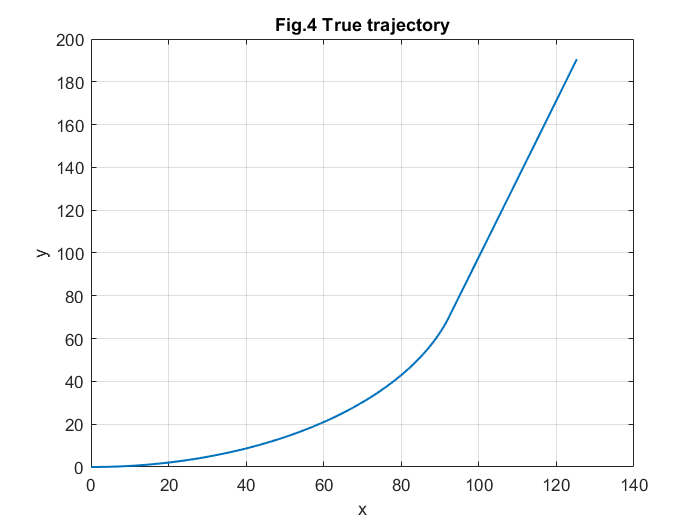

load('theta.mat')
n = 500;   % Size of trajectory 
T = 0.05;  % Interval between measurements

%Initial components of velocity
V = 10;
v = zeros(2,n);

% Initial coordinates
x = zeros(2,n);

% Random acceleration
var_a = 1;
a = sqrt(var_a)*randn(2,n);

for i = 2:n
    x(1,i) = x(1,i-1) + V*T*cos(theta(i-1)) + a(1,i-1)*T^2/2; % x
    x(2,i) = x(2,i-1) + V*T*sin(theta(i-1)) + a(2,i-1)*T^2/2; % y
    v(1,i)= V*cos(theta(i-1)); % V_x
    v(2,i)= V*sin(theta(i-1)); % V_y
end

figure
plot(x(1,:),x(2,:),'linewidth',1.2)
hold on
xlabel('x')
ylabel('y')
title('Fig.4 True trajectory')
grid on

##  Task 2: Generate measurements of x and y

var_eta_x = 3^2;
eta_x = randn(2,n)*sqrt(var_eta_x); 
z = x + eta_x;

##  Task 3: Generate measurements of velocity 𝑉

var_eta_V = 0.5^2;
eta_V = randn(1,n)*sqrt(var_eta_V);
V_meas = V + eta_V;

##  Task 4: Generate measurements of angle  Θ

var_eta_theta = 0.02^2;
eta_theta = randn(1,n)*sqrt(var_eta_theta);
theta_meas = theta + eta_theta;
z = vertcat(z,V_meas,theta_meas);

##  Task 5: Develop Extended Kalman filter assimilatin

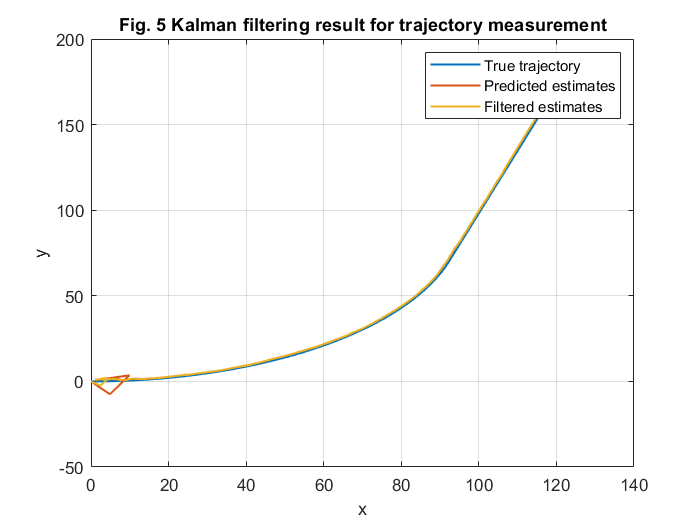

% Transition matrix
phi = eye(4) + T*diag(ones(3,1),1);
phi(2,3)=0;

% Input matrix
G = [T^2/2 0; T 0; 0 T^2/2;0 T];

% State noise covariance matrix
Q = G*G'*5^2;

% Initial filtered estimate of state vector
X = zeros(4,n);
X(:,2) = [z(1,2) (z(1,2)-z(1,1))/T z(2,2) (z(2,2)-z(2,1))/T]'; 

% Initial filtration error covariance matrix 
P = 1e4*eye(4); 

% Measurement noise covariance matrix R
R = zeros(4);
R(1,1) = var_eta_x;
R(2,2) = var_eta_x;
R(3,3) = var_eta_V;
R(4,4) = var_eta_theta;

X_pred = zeros(4,n);
h = zeros(4,n);
for i = 3:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    
    % h
    h(1,i) = X_pred(1,i);
    h(2,i) = X_pred(3,i);
    h(3,i) = sqrt(X_pred(2,i)^2+X_pred(4,i)^2);
    if X_pred(2,i)>0
        h(4,i) = atan(X_pred(4,i)/X_pred(2,i));
    elseif X_pred(2,i)<0 && X_pred(4,i)>0
        h(4,i) = atan(X_pred(4,i)/X_pred(2,i)) + pi;
     elseif X_pred(2,i)<0 && X_pred(4,i)<0
        h(4,i) = atan(X_pred(4,i)/X_pred(2,i)) - pi;
     elseif X_pred(2,i)==0 && X_pred(4,i)>0
        h(4,i) = pi/2;
     elseif X_pred(2,i)==0 && X_pred(4,i)<0
        h(4,i) = -pi/2;
    end
    
    % dh/dX
    dH = zeros(4);
    dH(1,1) = 1;
    dH(2,3) = 1;
    dH(3,2) = X_pred(2,i)/sqrt(X_pred(2,i)^2 + X_pred(4,i)^2);
    dH(3,4) = X_pred(4,i)/sqrt(X_pred(2,i)^2 + X_pred(4,i)^2);
    dH(4,2) = -X_pred(4,i)/(X_pred(4,i)^2 + X_pred(2,i)^2);
    dH(4,4) = X_pred(2,i)/(X_pred(2,i)^2 + X_pred(4,i)^2);

    % Filtration
    K = P_pred*dH'*inv(dH*P_pred*dH'+R);
    X(:,i) = X_pred(:,i) + K*(z(:,i)-h(:,i));
    P = (eye(4)-K*dH)*P_pred;
end

figure
plot(x(1,:),x(2,:),'linewidth',1.2)
hold on
plot(X_pred(1,:),X_pred(3,:),'linewidth',1.2)
plot(X(1,:),X(3,:),'linewidth',1.2)
xlabel('x')
ylabel('y')
legend('True trajectory','Predicted estimates','Filtered estimates')
title('Fig. 5 Kalman filtering result for trajectory measurement')
grid on

##  Task 5: Run Linear Kalman filter

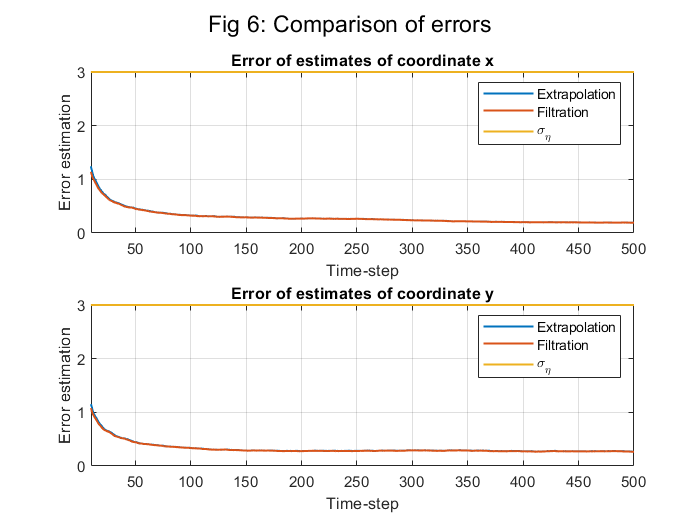

M = 500;

Final_Error_estr_2 = zeros(2,n);
error_estr = zeros(2,n);
Final_Error_filt_2 = zeros(2,n);
error_filt = zeros(2,n);
for run = 1:M      
    a = sqrt(var_a)*randn(2,n);

    for i = 2:n
        x(1,i) = x(1,i-1) + V*T*cos(theta(i-1)) + a(1,i-1)*T^2/2; % x
        x(2,i) = x(2,i-1) + V*T*sin(theta(i-1)) + a(2,i-1)*T^2/2; % y
        v(1,i)= V*cos(theta(i-1)); % V_x
        v(2,i)= V*sin(theta(i-1)); % V_y
    end

    % Generate measurements of x and y
    eta_x = randn(2,n)*sqrt(var_eta_x); 
    z = x + eta_x;
    % Generate measurements of velocity 𝑉
    eta_V = randn(1,n)*sqrt(var_eta_V);
    V_meas = V + eta_V;
    % Generate measurements of angle  Θ
    eta_theta = randn(1,n)*sqrt(var_eta_theta);
    theta_meas = theta + eta_theta;
    z = vertcat(z,V_meas,theta_meas);

    X = zeros(4,n);
    X(:,2) = [z(1,2) (z(1,2)-z(1,1))/T z(2,2) (z(2,2)-z(2,1))/T]'; 
    P = 1e4*eye(4); % Initial filtration error covariance matrix 

    X_pred = zeros(4,n);
    h = zeros(4,n);
    for i = 3:n
        % Prediction
        X_pred(:,i) = phi*X(:,i-1);
        P_pred = phi*P*phi' + Q;

        % h
        h(1,i) = X_pred(1,i);
        h(2,i) = X_pred(3,i);
        h(3,i) = sqrt(X_pred(2,i)^2+X_pred(4,i)^2);
        if X_pred(2,i)>0
            h(4,i) = atan(X_pred(4,i)/X_pred(2,i));
        elseif X_pred(2,i)<0 && X_pred(4,i)>0
            h(4,i) = atan(X_pred(4,i)/X_pred(2,i)) + pi;
         elseif X_pred(2,i)<0 && X_pred(4,i)<0
            h(4,i) = atan(X_pred(4,i)/X_pred(2,i)) - pi;
         elseif X_pred(2,i)==0 && X_pred(4,i)>0
            h(4,i) = pi/2;
         elseif X_pred(2,i)==0 && X_pred(4,i)<0
            h(4,i) = -pi/2;
        end

        % dh/dX
        dH = zeros(4);
        dH(1,1) = 1;
        dH(2,3) = 1;
        dH(3,2) = X_pred(2,i)/sqrt(X_pred(2,i)^2 + X_pred(4,i)^2);
        dH(3,4) = X_pred(4,i)/sqrt(X_pred(2,i)^2 + X_pred(4,i)^2);
        dH(4,2) = -X_pred(4,i)/(X_pred(4,i)^2 + X_pred(2,i)^2);
        dH(4,4) = X_pred(2,i)/(X_pred(2,i)^2 + X_pred(4,i)^2);

        % Filtration
        K = P_pred*dH'*inv(dH*P_pred*dH'+R);
        X(:,i) = X_pred(:,i) + K*(z(:,i)-h(:,i));
        P = (eye(4)-K*dH)*P_pred;
    end


    for i = 4:n
        %Errors of extrapolation estimates of coordinate x
        error_estr(1,i) = (x(1,i)-X_pred(1,i))^2;
        Final_Error_estr_2(1,i)= Final_Error_estr_2(1,i)+error_estr(1,i);
        %Errors of filtration estimates of of coordinate x
        error_filt(1,i) = (x(1,i)-X(1,i))^2;
        Final_Error_filt_2(1,i)= Final_Error_filt_2(1,i)+error_filt(1,i);
        
        %Errors of extrapolation estimates of coordinate y
        error_estr(2,i) = (x(2,i)-X_pred(3,i))^2;
        Final_Error_estr_2(2,i)= Final_Error_estr_2(2,i)+error_estr(2,i);
        %Errors of filtration estimates of coordinate y
        error_filt(2,i) = (x(2,i)-X(3,i))^2;
        Final_Error_filt_2(2,i)= Final_Error_filt_2(2,i)+error_filt(2,i);
    end
end
Final_Error_estr_2 = sqrt(Final_Error_estr_2/(M-1));
Final_Error_filt_2 = sqrt(Final_Error_filt_2/(M-1));

figure
subplot(2,1,1)
sgtitle("Fig 6: Comparison of errors")
plot(Final_Error_estr_2(1,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_2(1,:),'linewidth',1.2)
plot(sqrt(var_eta_x)*ones(1,n),'linewidth',1.2)
grid on
title('Error of estimates of coordinate x')
legend('Extrapolation','Filtration','\sigma_\eta')  
ylabel('Error estimation')
xlabel('Time-step')
xlim([10 inf])

subplot(2,1,2)
plot(Final_Error_estr_2(2,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_2(2,:),'linewidth',1.2)
plot(sqrt(var_eta_x)*ones(1,n),'linewidth',1.2)
title('Error of estimates of coordinate y')
legend('Extrapolation','Filtration','\sigma_\eta')  
ylabel('Error estimation')
xlabel('Time-step')
grid on
xlim([10 inf])

## Task 7: Compare the estimation accuracy in case of assimilating GPS data only and fusion of both GPS data and odometry data.

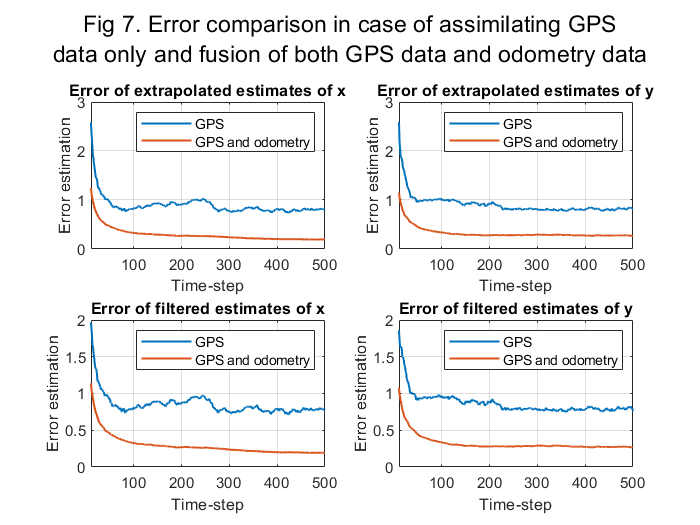

figure
sgtitle({'Fig 7. Error comparison in case of assimilating GPS' ...
    'data only and fusion of both GPS data and odometry data'})
subplot(2,2,1)
plot(Final_Error_estr_1(1,:), 'linewidth',1.2)
hold on
plot(Final_Error_estr_2(1,:),'linewidth',1.2)
grid on
title('Error of extrapolated estimates of x')
legend('GPS','GPS and odometry')  
ylabel('Error estimation')
xlabel('Time-step')
xlim([10 inf])

subplot(2,2,2)
plot(Final_Error_estr_1(2,:), 'linewidth',1.2)
hold on
plot(Final_Error_estr_2(2,:),'linewidth',1.2)
title('Error of extrapolated estimates of y')
legend('GPS','GPS and odometry')  
ylabel('Error estimation')
xlabel('Time-step')
grid on
xlim([10 inf])

subplot(2,2,3)
plot(Final_Error_filt_1(1,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_2(1,:),'linewidth',1.2)
grid on
title('Error of filtered estimates of x')
legend('GPS','GPS and odometry')  
ylabel('Error estimation')
xlabel('Time-step')
xlim([10 inf])

subplot(2,2,4)
plot(Final_Error_filt_1(2,:), 'linewidth',1.2)
hold on
plot(Final_Error_filt_2(2,:),'linewidth',1.2)
title('Error of filtered estimates of y')
legend('GPS','GPS and odometry')  
ylabel('Error estimation')
xlabel('Time-step')
grid on
xlim([10 inf])

## Task 7, General conclusions:

As it can be observed, when both GPS and odometry measurements are used, the Kalman Filter provides better accuracy and less fluctations.

The error estimation for extrapolated esimates of coordinates is asymptotically ~0.3, using  both GPS and odometry measurements, and ~0.8 using only GPS measurements.

For filtered estimates the trend is similar: the error estimation is asymptotically ~0.2, using  both GPS and odometry measurements, and ~0.7 using only GPS measurements.

## Conclusions:

- The true trajectory (Fig 4) and measurements for coordinates are generated as in Part 1. For the wheel odometry data, the velocity (V) is the average velocity of left and right wheels of the vehicle and its measurements are generated with the given variance. Also, the angle (Θ) comes simuntaneously with GPS data, the measurements are generated for the same.

- For assimilation of both GPS data and wheel odometry measurements an Extended Kalman filter alogorithm is developed considering all the initia conditions of X, phi, Q and G the same as in Part 1. The measurements vector changes and is a function of coordinates x & y, velocity and Θ. Since the measuremement vector is non-linear the h(X) function is created which relates the measurement vector z with state vector X. At filtration step the measurement is linearized by determining the derivative at the point of extrapolated estimated. Fig 5 shows the comparison of true, predicted and filtered estimates for the Extended Kalman filter which has some noise at initial time steps but becomes stable with true values as the time steps are increased. This states that we can use Extended Kalman filter to track the moving vehicle with assimilation of GPS data and odometry data.

- On running the filter for 500 runs only on the basis of GPS data and odometry data, in Fig 6 we can observe the error estimates for the coordinates of the vehicle. The errors of extrapolated and filtrations are almost ~12.8 times less than the standard deviation for coordinate x. Also, for coordinate y the errors of extrapolated and filtrations are ~10.8 times less than standard deviation.